clearvars
syms z N
assume(N>1)
Num(z)=1-z^(-N)

$$Num(z) = 1-\frac{1}{z^{N}}$$

Den(z)=1-z^(-1)

$$Den(z) = 1-\frac{1}{z}$$

H(z)= 1/N * Num(z)/Den(z)

$$H(z) = \frac{\frac{1}{z^{N}}-1}{N\,\left(\frac{1}{z}-1\right)}$$

% recherche des zéros
eqn1=Num(z)==0

$$eqn1 = 1-\frac{1}{z^{N}}=0$$

eqn1=simplify(eqn1)

$$eqn1 = \frac{1}{z^{N}}=1$$

[zeros,parameters,conditions] = solve(eqn1,z,'ReturnConditions',true)

$$zeros = {\mathrm{e}}^{\frac{2\,\pi \,k\,\mathrm{i}}{N}}$$

$$parameters = k$$

$$conditions = k\in \mathbb{Z}\wedge -\frac{N}{2}<k\wedge k\leq \frac{N}{2}$$

%recherche des pôles
eqn2= Den(z)== 0

$$eqn2 = 1-\frac{1}{z}=0$$

eqn2=simplify(eqn2)

$$eqn2 = z=1$$

poles = solve(eqn2,z)

$$poles = 1$$


syms w
H

$$H(z) = \frac{\frac{1}{z^{N}}-1}{N\,\left(\frac{1}{z}-1\right)}$$

H=subs(H,z,exp(j*w))

$$H(z) = \frac{\frac{1}{{\left({\mathrm{e}}^{w\,\mathrm{i}}\right)}^{N}}-1}{N\,\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}$$

assume(w,'real')
H=subs(H,N,4) % instantiation de N =2 N=6 etc ...

$$H(z) = \frac{{\mathrm{e}}^{-4\,w\,\mathrm{i}}-1}{4\,\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}$$

H=simplify(H)

$$H(z) = \frac{{\mathrm{e}}^{-4\,w\,\mathrm{i}}-1}{4\,\left({\mathrm{e}}^{-w\,\mathrm{i}}-1\right)}$$

modH=sqrt(real(H)^2+imag(H)^2)

$$modH(z) = \begin{array}{l} \sqrt{{\left(\frac{\sin\left(4\,w\right)\,\sin\left(w\right)}{\sigma_{1}}+\frac{\left(\cos\left(w\right)-1\right)\,\left(\cos\left(4\,w\right)-1\right)}{\sigma_{1}}\right)}^{2}+{\left(\frac{\sin\left(4\,w\right)\,\left(\cos\left(w\right)-1\right)}{\sigma_{1}}-\frac{\sin\left(w\right)\,\left(\cos\left(4\,w\right)-1\right)}{\sigma_{1}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=4\,\left({\sin\left(w\right)}^{2}+{\left(\cos\left(w\right)-1\right)}^{2}\right) \end{array}$$

simplify(modH)

$$ans(z) = \frac{\sqrt{2}\,\left|\cos\left(w\right)\right|\,\sqrt{\cos\left(w\right)+1}}{2}$$

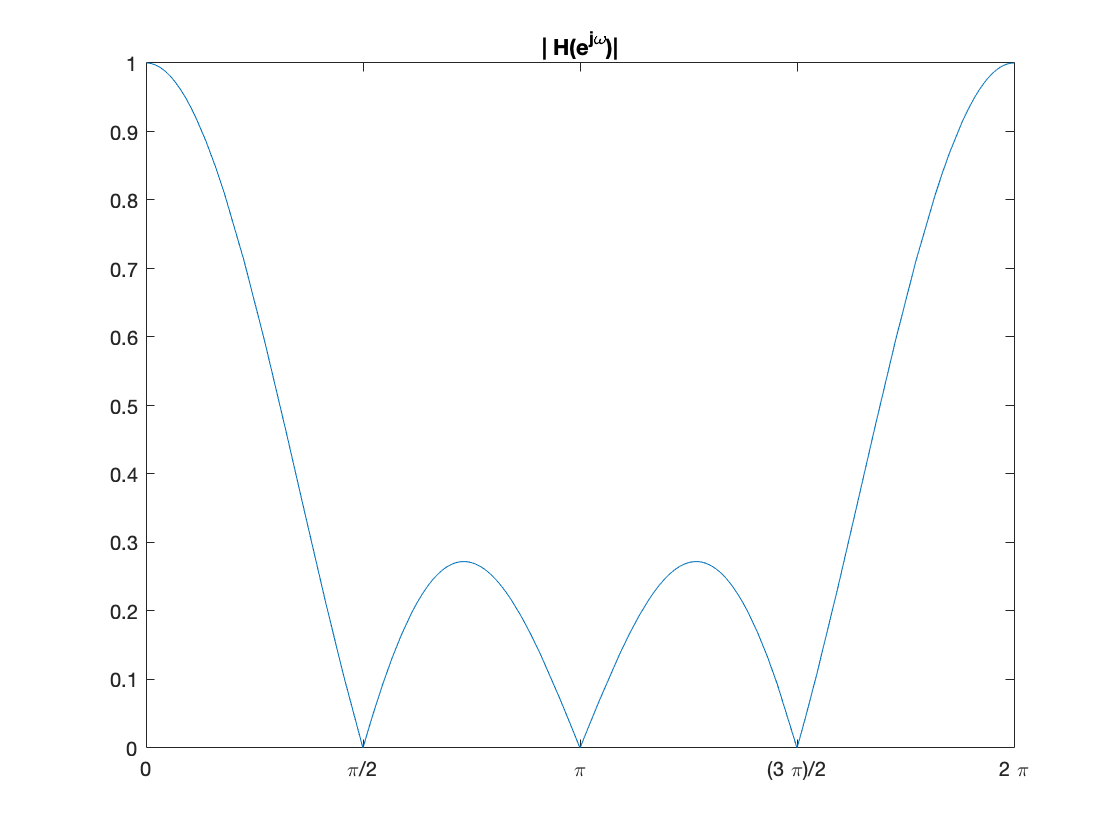

fplot(modH(w),[0 2*pi])
% graduation pour fonction trigo
ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));     
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
title('| H(e^{j\omega})|')

syms z w n

% Le 1er filtre
Num1(z)=(1-0*z^(-1))*(1-0*z^(-1))

$$Num1(z) = 1$$

Den1(z)=(1-0.5*z^(-1))*(1-0.2*z^(-1))

$$Den1(z) = \left(\frac{1}{2\,z}-1\right)\,\left(\frac{1}{5\,z}-1\right)$$

S1(z)=Num1/Den1(z);
S1=simplify(S1)

$$S1(z) = \frac{10\,z^{2}}{10\,z^{2}-7\,z+1}$$

% Le 2ème filtre
S2(z)= (10-7*z^(-1)+1*z^(-2))

$$S2(z) = \frac{1}{z^{2}}-\frac{7}{z}+10$$

eqn2=S2(z)==0

$$eqn2 = \frac{1}{z^{2}}-\frac{7}{z}+10=0$$

zero2 = solve(eqn2,z)

$$zero2 = \left(\begin{array}{c} \frac{1}{5}\\ \frac{1}{2} \end{array}\right)$$

% Le produit des deux
S12(z)=S1(z)*S2(z)

$$S12(z) = \frac{10\,z^{2}\,\left(\frac{1}{z^{2}}-\frac{7}{z}+10\right)}{10\,z^{2}-7\,z+1}$$

S12=simplify(S12)

$$S12(z) = 10$$